# **Trend Decomposition and Clustering**

In this example, we decompose each commodity price series into a long-term trend, a seasonal component, and an irregular (or business cycle) component. This is an additive decomposition:


$$P_t = L_t + S_t + C_t, \quad t = 1, 2, 3, \dots,$$


where

- $P_t$ is the commodity price series,

- $L_t$ is the long-term trend,

- $S_t$ is the seasonal component (which may be the sum of multiple seasonal trends),

- $C_t$ is the irregular component.

Based on the relative similarity of the irregular components of the commodity price series, we then cluster the commodities into groups using unsupervised machine learning techniques.

*Copyright 2022 The MathWorks, Inc.*

## Load the commodity data.

load( "Commodities.mat" )

## Decompose the commodity prices.

Preallocate variables for the series components.

numObservations = height( Prices );
numCommodities = width( Prices );
commodityNames = Prices.Properties.VariableNames;

longTermComponent = NaN( numObservations, numCommodities );
seasonalComponent = NaN( numObservations, numCommodities );
irregularComponent = NaN( numObservations, numCommodities );
regularComponent = NaN( numObservations, numCommodities );

Create tiled layouts for the visualization. We will visualize the trend components (i.e., the sum of $L_t$ and $S_t$) separately from the irregular components ($C_t$).

figure
tlTrend = tiledlayout( "flow" );
title( tlTrend, "Trend Components" )

figure
tlIrregular = tiledlayout( "flow" );
title( tlIrregular, "Irregular Components")

For each commodity price series, perform the trend decomposition using [`trenddecomp`](matlab: doc trenddecomp).

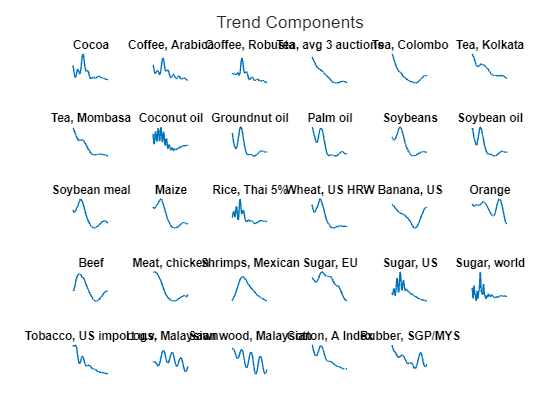

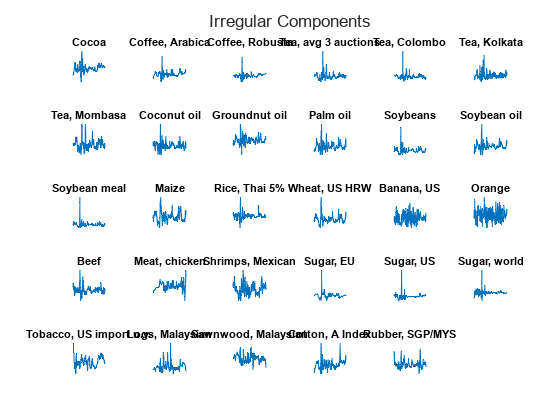

for k = 1:numCommodities

    % Decompose the price series and store the results. There may be more
    % than one seasonal component identified by this process, so sum the
    % resulting matrix of seasonal components to obtain the overall
    % seasonal trend.
    [L, S, C] = trenddecomp( Prices{:, k} );
    longTermComponent(:, k) = L;
    seasonalComponent(:, k) = sum( S, 2 );
    irregularComponent(:, k) = C;
    regularComponent(:, k) = longTermComponent(:, k) + seasonalComponent(:, k);

    % Add the components to the visualization.
    nexttile(tlTrend)
    plot(Prices.Date, regularComponent(:, k) )
    title(commodityNames(k))
    axis off

    nexttile(tlIrregular)
    plot(Prices.Date, irregularComponent(:, k))
    title(commodityNames(k))
    axis off

end

From the trend decomposition and inspecting the series $L_t+S_t$ for each commodity, most commodities have shown a long-term decrease in price over recent decades, followed by a more recent upturn in the price. 

There are some exceptions, such as the series *Sugar, EU*, where the long-term trend is downwards. 

Some commodities also appear to have gone through periods of high seasonal volatility, such as the two coffee price series. Banana and orange prices appear to be more susceptible to seasonal volatility. Chicken prices exhibit seasonal volatility which has increased in the last few years.

## Cluster the commodites based on the similarity in their irregular component.

After removing the long-term and seasonal components from the price series, we are left with the irregular component $C_t$, given by

$C_t = P_t - L_t - S_t$.

This component is also regarded as representing the business cycle component in the time series, affected by short-term market conditions. It provides a fairer basis for comparing the commodity prices, since both the long-term price trends and seasonal trends have been removed.

Compute the pairwise distances between the irregular components using the correlation distance metric $d$. This is defined by

$d(s_1, s_2) = 1-\rho(s_1, s_2)$, where $\rho(s_1, s_2)$ is the linear correlation coefficient between the two time series $s_1$ and $s_2$.

irregularCorrDistances = pdist( irregularComponent.', "correlation" );

Perform [hierarchical clustering](matlab: doc linkage) using the correlation distances. The `complete` method uses the largest distance between commodities in the two clusters.

irregularComponentLinkage = linkage( irregularCorrDistances, "complete" );

Create a [`dendrogram`](matlab: doc dendrogram) to visualize the linkage.

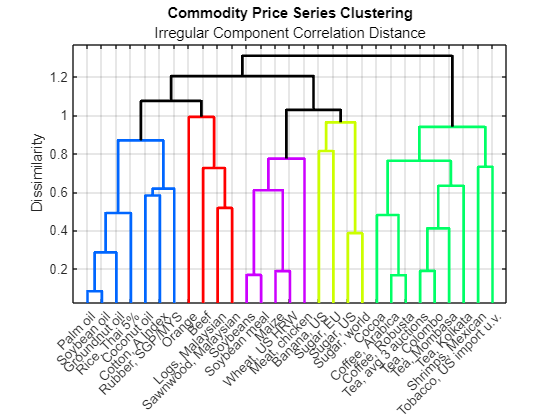

figure
h = dendrogram( irregularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 1 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Irregular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

Cluster the commodities into 5 groups based on their similarity obtained from this method.

numClusters = 5;
Group = cluster( irregularComponentLinkage, "maxclust", numClusters );
Commodity = string( commodityNames.' );
clusteredCommodities = table( Commodity, Group );
commoditiesByCluster = sortrows( clusteredCommodities, "Group" );
disp( commoditiesByCluster )

            Commodity            Group
    _________________________    _____

    "Soybeans"                     1  
    "Soybean meal"                 1  
    "Maize"                        1  
    "Wheat, US HRW"                1  
    "Meat, chicken"                1  
    "Banana, US"                   2  
    "Sugar, EU"                    2  
    "Sugar, US"                    2  
    "Sugar, world"                 2  
    "Coconut oil"                  3  
    "Groundnut oil"                3  
    "Palm oil"                     3  
    "Soybean oil"                  3  
    "Rice, Thai 5%"                3  
    "Cotton, A Index"              3  
    "Rubber, SGP/MYS"              3  
    "Orange"                       4  
    "Beef"                         4  
    "Logs, Malaysian"              4  
    "Sawnwood, Malaysian"          4  
    "Cocoa"                        5  
    "Coffee, Arabica"             

## Repeat the clustering based on the similarity in the regular component.

The regular component is the sum of the long-term and seasonal trends $L_t+S_t$, and is equal to $P_t-C_t$, the commodity price series without its irregular (business cycle) component.

Evaluate the pairwise distances and the corresponding linkage.

regularCorrDistances = pdist( regularComponent.', "correlation" );
regularComponentLinkage = linkage( regularCorrDistances, "complete" );

Create a dendrogram to visualize the linkage, and select a threshold in order to achieve three clusters.

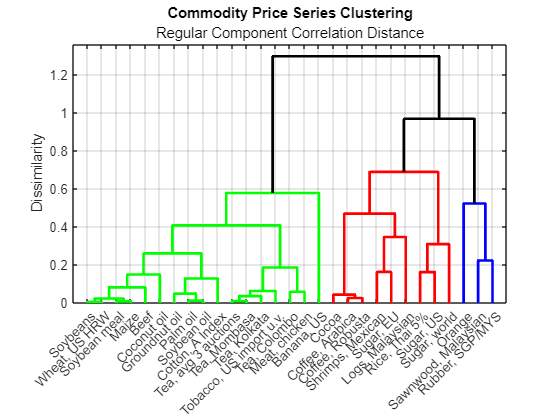

figure
h = dendrogram( regularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 0.8 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Regular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

We might expect the volatility present within the commodities to manifest itself in the irregular component, rather than the regular component. For this reason we continue with the clusters identified by performing hierarchical clustering on the irregular components of the commodity price series. However, clustering on the regular components provides a useful grouping of the commodities based on their combined long-term and seasonal trends. From the dendrogram we observe that both oranges and bananas have a dissimilar regular profile to the other commodities

## Visualize the commodity clusters by creating an embedding in 3D space.

Embed the commodities in a lower-dimensional space using classical multi-dimensional scaling ([`cmdscale`](matlab: doc cmdscale)).

lowerDim = 3;
Y = cmdscale( irregularCorrDistances, lowerDim );

Visualize the embedding. Add the convex hull of each group to illustrate the different groupings in 3D space.

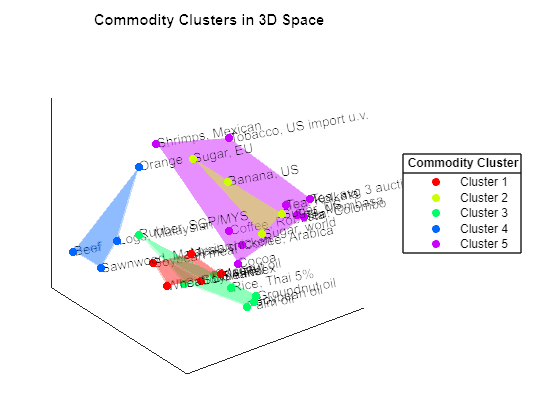

figure
view( 3 )
clusterColors = hsv( numClusters );
colormap( clusterColors )
hold( "on" )

for k = 1:numClusters
    % Extract coordinate data for the current group.
    idx = clusteredCommodities.Group == k;
    clusterx = Y(idx, 1);
    clustery = Y(idx, 2);
    clusterz = Y(idx, 3);
    color = clusterColors(k, :);
    % Evaluate the convex hull.
    ch = convhull( clusterx, clustery, clusterz );
    % Visualize the convex hull, its vertices (the commodities), and create
    % text labels.
    trisurf( ch, clusterx, clustery, clusterz, ...
        "FaceColor", clusterColors(k, :), ...
        "FaceAlpha", 0.25, ...
        "EdgeColor", "none", ...
        "HandleVisibility", "off" )
    scatter3( clusterx, clustery, clusterz, ...
        [], clusterColors(k, :), "filled", "DisplayName", "Cluster " + k )
    text( clusterx, clustery, clusterz, ...
        clusteredCommodities.Commodity(idx), "Rotation", 10 )
end

xticks( [] )
yticks( [] )
zticks( [] )
title( "Commodity Clusters in 3D Space" )
lg = legend( "Location", "eastoutside" );
title( lg, "Commodity Cluster" )